## **Soft Gripper Finger Actuation** 

A modular gripper finger is constructed by connecting rigid links using soft links that woud act like distributed joints. The soft links are allowed to bend about the z-axis with a strain order of 1 to enable the bending of the finger.

SorosimLinks (Soft and Rigid), and SorosimLinkage (Finger) are saved in GripperFinger`.mat`

load('GripperFinger.mat')

To see the properties of Soft

Soft

Soft =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
           CS: 'R'
         npie: 2
           lp: {[0.0100]}
            L: 0.0100
            r: {[]}
            h: {@(X1)0.005}
            w: {@(X1)0.015}
            a: {[]}
            b: {[]}
           gi: {[4×4 double]}
           gf: {[4×4 double]}
            E: 1000000
          Poi: 0.5000
            G: 3.3333e+05
          Eta: 10000
          Rho: 1000
           Kj: []
           Dj: []
            M: []
          n_l: 25
          n_r: []
        color: [0.7655 0.7952 0.1869]
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.0091


To see the properties of Rigid

Rigid

Rigid =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 'r'
           CS: 'R'
         npie: 1
           lp: []
            L: 0.0200
            r: []
            h: @(X1)0.012
            w: @(X1)0.02
            a: []
            b: []
           gi: [4×4 double]
           gf: [4×4 double]
            E: []
          Poi: []
            G: []
          Eta: []
          Rho: 1000
           Kj: []
           Dj: []
            M: [6×6 double]
          n_l: 25
          n_r: []
        color: [0.4898 0.4456 0.6463]
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.0169


To see the properties of Finger

Finger

Finger =   SorosimLinkage with properties:

                   N: 6
                ndof: 6
                nsig: 30
              VLinks: [1×2 SorosimLink]
           LinkIndex: [6×1 double]
            CVTwists: {6×1 cell}
               iLpre: [6×1 double]
               g_ini: [24×4 double]
             Z_order: 4
                nCLj: []
                iACL: []
                iCLB: []
          VTwistsCLj: []
               gACLj: []
               gBCLj: []
        CLprecompute: [1×1 struct]
                T_BS: []
             Gravity: 0
                   G: 0
          PointForce: 0
       FollowerForce: []
                  np: []
              Fp_loc: []
              Fp_vec: []
                CEFP: 0
             M_added: []
            Actuated: 1
                nact: 1
                Bqj1: []
              n_jact: 0
              i_jact: []
             i_jactq: []
    WrenchControlled: []
      

To see the problem definition:

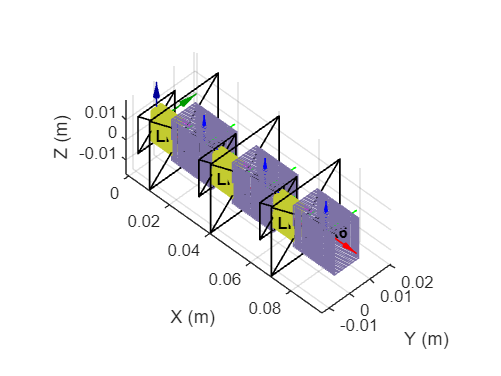

Finger.plotq0

The result should be:

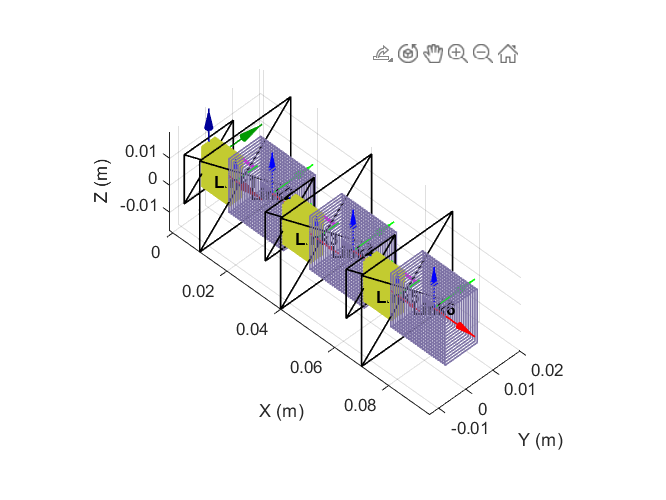

The gripper finger is rigidly fixed at one end and can be subjected to actuation forces.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Time-advancing

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          7           1.715e+10                        1.37e+10              1
     1         14         3.94966e-21       0.775959         6.44e-06              1
     2         21         5.79563e-56    7.57071e-16         1.25e-23           1.94

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

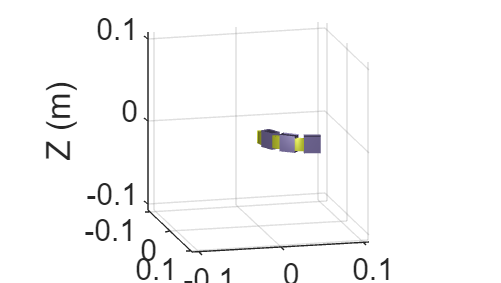

q=Finger.statics;

Enter -1 N as the input actuation force into the cable in the command window when prompted. A dialog box will pop up, asking for the initial guess the user can choose the default value. 

The equilibirum solution is,

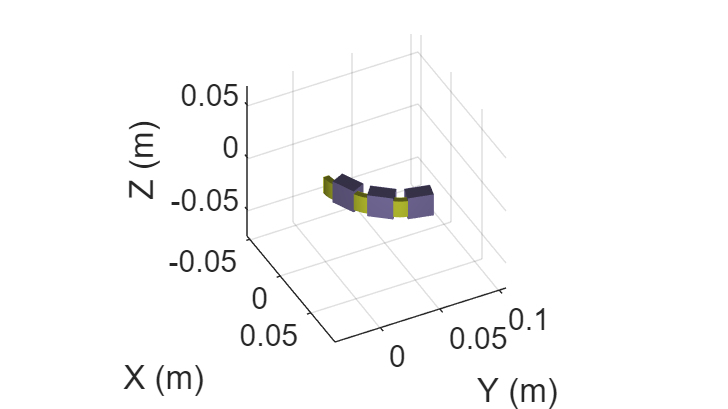

### **Dynamics (not recommended for this example)**

For dynamics problem, type:

    0.0071

    0.0713

    0.3624

    0.5411

    0.8901

    1.0091

    1.1812

    1.5258

    2.4747

    3.8498

    3.7755

    3.8413

    3.8706

    3.8656

    3.8960

    4.6207

Elapsed time is 6.200363 seconds.


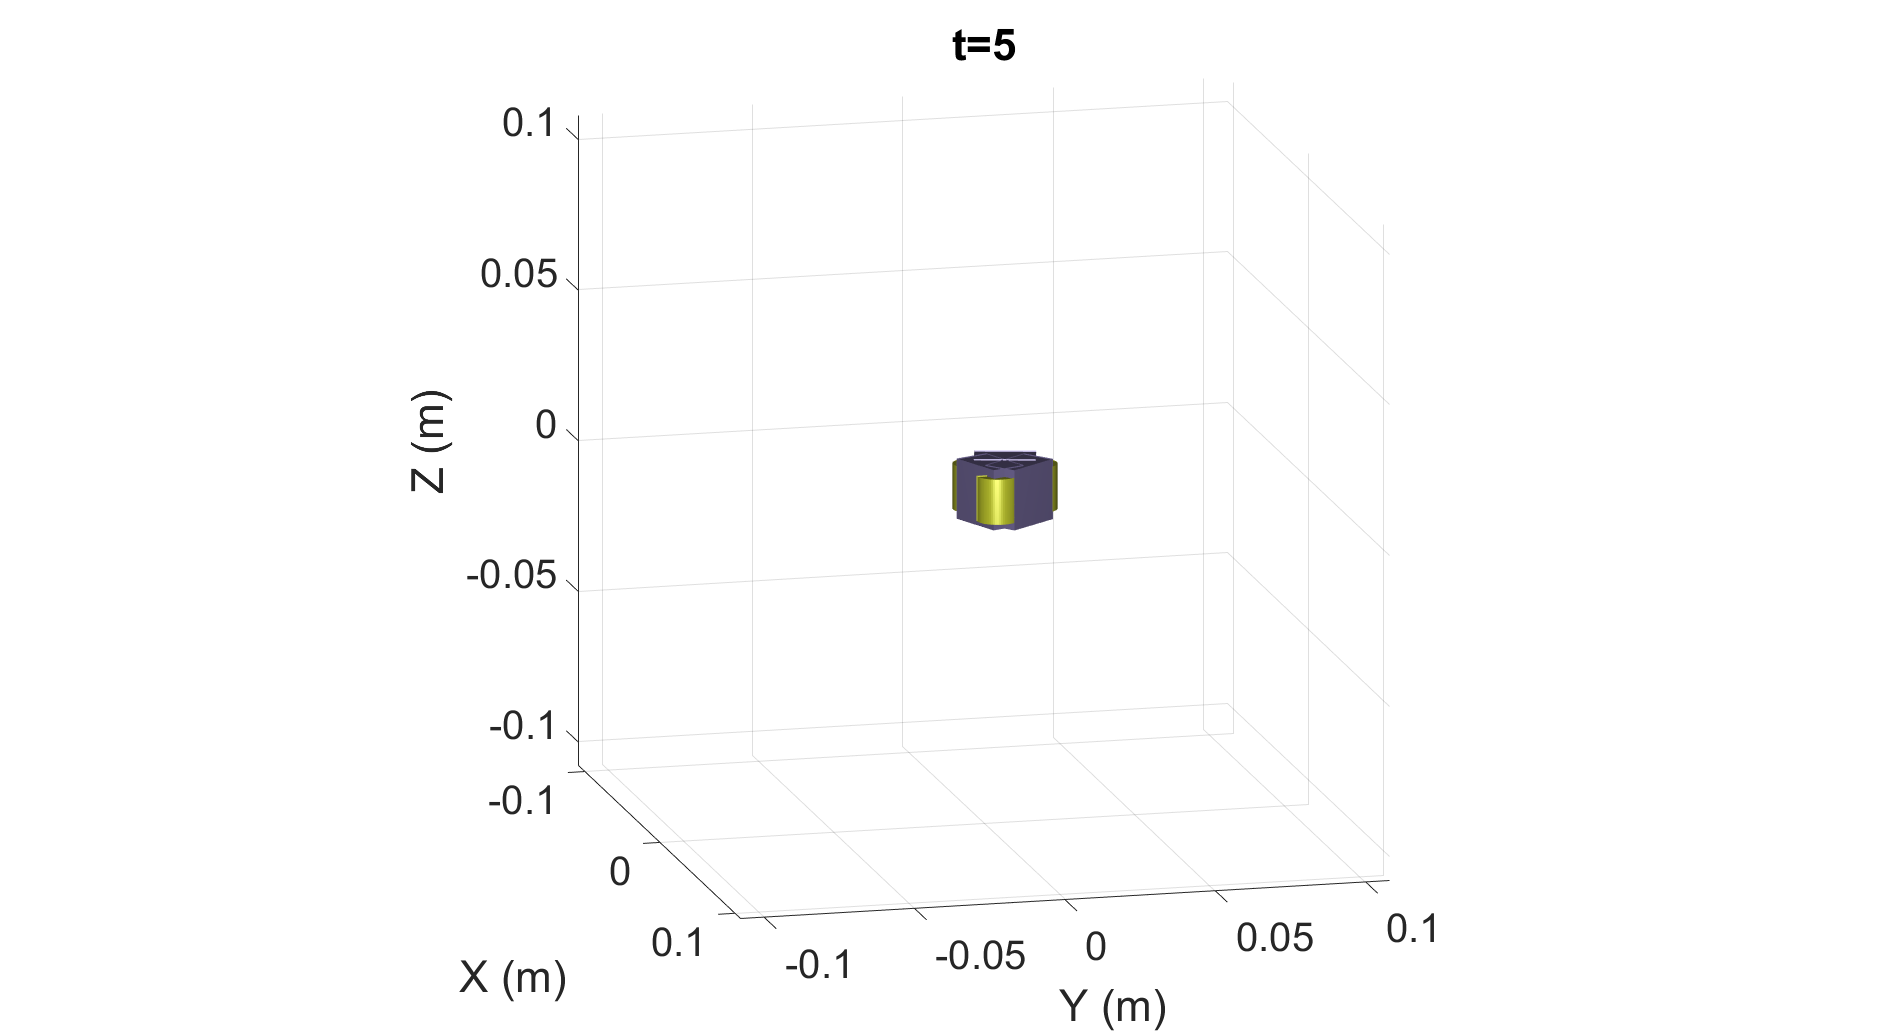

[t,qqd]=Finger.dynamics([],'ode15s');

The actuation input to the cable can be input by the user as a function of t in the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time. Especially for this example the time is **very high.**

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.